addpath(genpath('/Users/teatompos/Desktop/Matlab_scripts'))
clear all; close all; 

In this notebook I will set up the pipeline for the network exclusion based on 1 criterion: correlation of the cortical population activity with the thalamic population. I will test 100 network seeds (which affect the connectivity structure) and evaluate the correlation per layer and population. Then, I will create a histogram of correlation values. At last, I will choose a threshold for each histogram. The seeds that pass this exclusion criterion will be considered in my later work.

% set the seed number
seedNum = 100;

% % how many workers are available for parallel processing
% gcp_props = gcp;
% gcp_props.NumWorkers

% % how many workers do you wanna use?
% workNum = 4;

% run the network
clearvars -except SpikingNetwork seedNum
cd '/Users/teatompos/Library/CloudStorage/GoogleDrive-t.tompos@neurophysiology.nl/.shortcut-targets-by-id/1f3yqxuDDFP_-nrGlSKbqcVC3RJJZZWTiWyK5Kl5x65maOi21i1OEIloSOR_UsCfsdiH2FbZf/Lab notebook Tea Tompoš/Thesis/Chapter 2 (The model)/Simulations/ExclusionCriteria'

synScalingFactors = 1;
pconnScalingFactors = 1;

synParams = struct('synstr',[synScalingFactors synScalingFactors], 'pconn', [pconnScalingFactors pconnScalingFactors]);

Ecells_percentage = 0.85;
Icells_percentage = 0.15;

tstop = 2000; % simulation time in ms

XCorrAnalysis = table([],[],[],[],[],[],[],[],[],'variablenames',{'seed', 'pop', 'sim_dur','ctx_spk_times', 'vpm_spk_times', 'num_responsive_cells','first_spk_latency', 'second_spk_latency', 'xcorr_data'});

r = 1;
analyse = 1;

minDistVPMevent = 20; % ms
multiBins = [3 5 8 10 12]; % ms

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];

for s_num = 1:seedNum
    NetSaveName = sprintf('N4_rep%i_seed%i', r, s_num);
    if ~analyse
        SpikingNetwork = SimN4(Ecells_percentage, Icells_percentage, [], synParams, [], [], 'synthetic', s_num, tstop);
        
        % save the network
        ParallelSave(NetSaveName,SpikingNetwork)
    else
        load(NetSaveName)
    end
    % simulation duration
    sim_dur = SpikingNetwork.time(end); % in ms
    
    % FIRST: isolate thalamic events and the corresponding cortical activity
    time = [SpikingNetwork.time(1) SpikingNetwork.time(end) SpikingNetwork.simulator_options.dt];
    fullTime = time(1):time(3):time(2);
    cutStartTime = 100; % ms
    try
        combinedVPMpops = [SpikingNetwork.VPMcorr_V SpikingNetwork.VPMuncorr_V];
    catch ME
        combinedVPMpops = SpikingNetwork.VPM_V;
    end
    
    % VPM spikes
    VPMspikes = getSpikeTimes(combinedVPMpops,fullTime);
    VPMactivity = cellfun(@(x) x(x>cutStartTime), VPMspikes, 'uniformoutput', false); % remove spikes happening before the cut-time
    
    for pop = 1:length(pops)
        % pop name
        pName = pops(pop,:);
        % ctx spikes
        CTXspikes = getSpikeTimes(SpikingNetwork.([pName '_V']), fullTime);
        CTXactivity = cellfun(@(x) x(x>cutStartTime), CTXspikes, 'uniformoutput', false);
        
        if pop > 1
            clear allXCorrBins FSL SSL
            allXCorrBins.BinSizeInMs = [];
            allXCorrBins.MaxXCorrVals = [];
            allXCorrBins.MaxXCorrTime = [];
            FSL.BinSizeInMs = [];
            FSL.Latency = [];
            SSL.BinSizeInMs = [];
            SSL.Latency = [];
        end
        
        for bnum = 1:length(multiBins)
            binSize_events = multiBins(bnum);
            [vpm_psth, vpm_edges] = plotPsthAndRaster('psth',VPMactivity,binSize_events,time(2),0); % edges are given in time (ms) with timestep = binSize_events
            minVPMevent_height = mean(vpm_psth) + (0.5*std(vpm_psth));
            
            [~, vpm_events_location] = findpeaks(vpm_psth,'minpeakheight',minVPMevent_height,'minpeakdistance',round(minDistVPMevent/binSize_events),'sortstr','descend');
            time_vec_vpm = vpm_edges(vpm_events_location);
            
            ctx_psth = plotPsthAndRaster('psth',CTXactivity,binSize_events,time(2),0);
            
            % get pre- and post-peak boundaries
            time_pre = 50; % ms pre peak
            time_post = 100; % ms post peak
            pre = round(time_pre/binSize_events);
            post = round(time_post/binSize_events);
            
            % loop through vpm events and get ctx psth activity
            xcorrVals = [];
            timeShift = [];
            responsiveCellsNum = [];
            first_spk_lat = [];
            second_spk_lat = [];
            for ev = 1:length(time_vec_vpm)
                if time_vec_vpm(ev)+time_post > vpm_edges(end) % handle the right edge
                    last_idx = length(vpm_edges);
                    pad_back = zeros(1,round(abs(diff([time_vec_vpm(ev)+time_post  vpm_edges(end)]))/binSize_events));
                else
                    last_idx = nearest(vpm_edges, time_vec_vpm(ev))+post;
                    pad_back = [];
                end
                if time_vec_vpm(ev)-time_pre < vpm_edges(1) % handle the left edge
                    first_idx = 1;
                    pad_front = zeros(1,round(abs(diff([time_vec_vpm(ev)-time_post  vpm_edges(1)]))/binSize_events));
                else
                    first_idx = nearest(vpm_edges, time_vec_vpm(ev)-pre);
                    pad_front = [];
                end
                
                vpm_ev = [pad_front vpm_psth(first_idx:last_idx) pad_back];
                ctx_ev = [pad_front ctx_psth(first_idx:last_idx) pad_back];
                
                % get how many cells participate in this event
                EventStartTime = vpm_edges(first_idx);
                EventEndTime = vpm_edges(last_idx);
                
                CTXactivity_ThisEvent = cellfun(@(x) x(x>EventStartTime & x<EventEndTime), CTXspikes, 'uniformoutput', false);
                
                responsiveCells = cell2mat(cellfun(@(x) ~isempty(x), CTXactivity_ThisEvent, 'uniformoutput', false));
                responsiveCellsNum(end+1) = length(find(responsiveCells>0));
                
                % LATENCY
                ltc_first = []; ltc_second = [];
                for nrn = 1:size(CTXspikes,2)
                    first_spike_time = CTXspikes{1, nrn}(find(CTXspikes{1, nrn}>EventStartTime,1,'first'));
                    second_spike_time = CTXspikes{1, nrn}(find(CTXspikes{1, nrn}>EventStartTime,2,'first'));
                    
                    if isempty(first_spike_time)
                        first_spike_time = NaN;
                        second_spike_time = NaN;
                    end
                    if length(second_spike_time)<=1
                        second_spike_time = NaN;
                    else
                        second_spike_time = second_spike_time(2);
                    end
                                    
                    ltc_first(nrn,1) = first_spike_time - EventStartTime;
                    ltc_second(nrn,1) = second_spike_time - EventStartTime;
                end
                first_spk_lat{ev} = ltc_first;
                second_spk_lat{ev} = ltc_second;
                
                % SECOND: calculate xcorr
                cross_corr = xcorr(vpm_ev, ctx_ev);
                
                % Get the maximum value of the cross-correlation
                [max_cross_corr, idx] = max(cross_corr);
                
                % Calculate the temporal shift. Subtract the length of one signal to correct for the zero-padding in xcorr
                temporal_shift_bins = idx - length(vpm_ev);
                
                % Convert the temporal shift from bins to ms
                temporal_shift_ms = temporal_shift_bins * binSize_events;
                timeShift(end+1) = temporal_shift_ms;
                
                % THIRD: get the xcorr value
                if abs(temporal_shift_ms) > 100 % ms
                    xcorrVals(end+1) = NaN;
                else
                    xcorrVals(end+1) = max_cross_corr;
                end
            end
            allXCorrBins(bnum).BinSizeInMs = binSize_events;
            allXCorrBins(bnum).MaxXCorrVals = {xcorrVals};
            allXCorrBins(bnum).MaxXCorrTime = {timeShift};
            
            FSL(bnum).BinSizeInMs = binSize_events;
            FSL(bnum).Latency = first_spk_lat;
            
            SSL(bnum).BinSizeInMs = binSize_events;
            SSL(bnum).Latency = second_spk_lat;
        end
        XCorrAnalysis = [XCorrAnalysis; table({['seed' num2str(s_num)]},{pName},sim_dur,{CTXspikes},{VPMspikes},{responsiveCellsNum},{FSL},{SSL},{allXCorrBins},...
            'variablenames',{'seed', 'pop', 'sim_dur','ctx_spk_times', 'vpm_spk_times', 'num_responsive_cells', 'first_spk_latency', 'second_spk_latency', 'xcorr_data'})];
    end
end

return

## XCORR analysis: an example

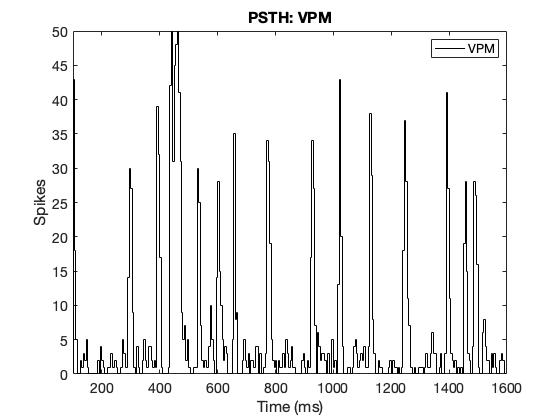

clearvars -except SpikingNetwork
time = [SpikingNetwork.time(1) SpikingNetwork.time(end) SpikingNetwork.simulator_options.dt];
fullTime = time(1):time(3):time(2);
cutStartTime = 100; % ms

% plot the thalamic activity
binSize = 5; % ms

try
    combinedVPMpops = [SpikingNetwork.VPMcorr_V SpikingNetwork.VPMuncorr_V];
catch ME
    combinedVPMpops = SpikingNetwork.VPM_V;
end

VPMspikes = getSpikeTimes(combinedVPMpops,fullTime);
VPMactivity = cellfun(@(x) x(x>cutStartTime), VPMspikes, 'uniformoutput', false); % remove spikes happening before the cut-time

figure;clf;
plotPsthAndRaster('psth',VPMactivity,binSize,time(2),1,'k');

ylabel('Spikes')
xlabel('Time (ms)')
xlim([cutStartTime time(2)])
legend("VPM")
title('PSTH: VPM')
set(gca,'fontsize', 14)

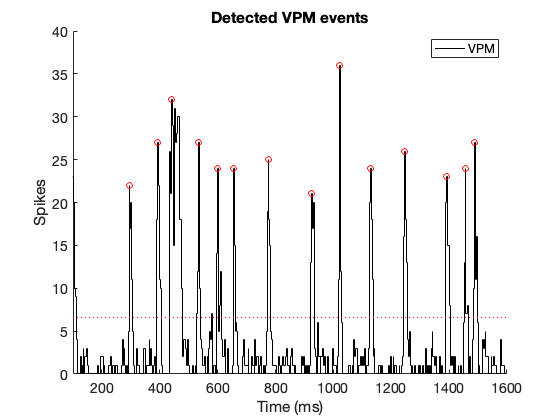

% detect events in the VPM PSTH
minDistVPMevent = 20;
binSize_events = 3;

[vpm_psth, vpm_edges] = plotPsthAndRaster('psth',VPMactivity,binSize_events,time(2),0); % edges are given in time (ms) with timestep = binSize_events
minVPMevent_height = mean(vpm_psth) + (0.5*std(vpm_psth));

[~, vpm_events_location] = findpeaks(vpm_psth,'minpeakheight',minVPMevent_height,'minpeakdistance',round(minDistVPMevent/binSize_events),'sortstr','descend');

% % adjust events (shift peak if any of the 3 preceeding bins have >spikes_thresh spikes
% for ev = 1:length(vpm_events_location)
%     if any(vpm_psth([vpm_events_location(ev)-3:vpm_events_location(ev)-1])>minVPMevent_height)
%         bin_shift_idx = find(vpm_psth([vpm_events_location(ev)-3:vpm_events_location(ev)])>minVPMevent_height);
%         bin_shift = abs(diff([bin_shift_idx(1) bin_shift_idx(end)]));
%         vpm_events_location(ev) = vpm_events_location(ev)-bin_shift;
%     end
% end
time_vec_vpm = vpm_edges(vpm_events_location);

% plot detected events
figure; clf; hold on;
plotPsthAndRaster('psth',VPMactivity,binSize_events,time(2),1,'k');
plot(vpm_edges(vpm_events_location), vpm_psth(vpm_events_location),'or')
plot(xlim,[minVPMevent_height minVPMevent_height],':r')

ylabel('Spikes')
xlabel('Time (ms)')
xlim([cutStartTime time(2)])
legend("VPM")
title('Detected VPM events')
set(gca,'fontsize', 14)

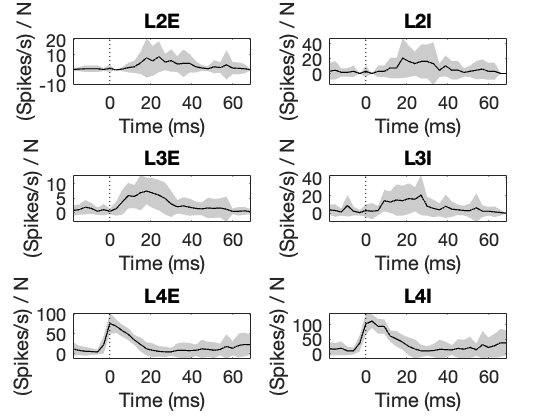

% get ctx psth
ctxEvents = [];
pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];

figure; tiledlayout(3,2);

for pop = 1:length(pops)
    pName = pops(pop,:);
    CTXspikes = getSpikeTimes(SpikingNetwork.([pName '_V']), fullTime);
    CTXactivity = cellfun(@(x) x(x>cutStartTime), CTXspikes, 'uniformoutput', false);
    
    ctx_psth = plotPsthAndRaster('psth',CTXactivity,binSize_events,time(2),0);
    
    % get pre- and post-peak boundaries
    time_pre = 50; % ms pre peak
    time_post = 70; % ms post peak
    pre = round(time_pre/binSize_events);
    post = round(time_post/binSize_events);
    
    % loop through vpm events and get ctx psth activity
    results = [];
    for ev = 1:length(time_vec_vpm)
        if time_vec_vpm(ev)+time_post > vpm_edges(end) % handle the right edge
            last_idx = length(vpm_edges);
            pad_back = zeros(1,round(abs(diff([time_vec_vpm(ev)+time_post  vpm_edges(end)]))/binSize_events));
        else
            last_idx = nearest(vpm_edges, time_vec_vpm(ev))+post;
            pad_back = [];
        end
        if time_vec_vpm(ev)-time_pre < vpm_edges(1) % handle the left edge
            first_idx = 1;
            pad_front = zeros(1,round(abs(diff([time_vec_vpm(ev)-time_post  vpm_edges(1)]))/binSize_events));
        else
            first_idx = nearest(vpm_edges, time_vec_vpm(ev)-pre);
            pad_front = [];
        end
        
        results.vpm_events{ev} = [pad_front vpm_psth(first_idx:last_idx) pad_back];
        results.ctx_events{ev} = [pad_front ctx_psth(first_idx:last_idx) pad_back];
        
%         if ev>1
%             if length(results.vpm_events{ev-1}) ~= length(results.vpm_events{ev})
%                 p;
%             end
%         end
    
        ev_time = [time_vec_vpm(ev)-time_pre time_vec_vpm(ev) time_vec_vpm(ev)+time_post]; % [pre_bound_time peak_time post_bound_time]
        results.event_times{ev} = ev_time;
    end
    % plot events
    nexttile; 
    fr_converter1 = (binSize_events/1000); % turn bins into seconds
    fr_converter2 = size(SpikingNetwork.([pName '_V']),2); % average over number of neurons N
    data = cell2mat(results.ctx_events');
    
    event_start = find(mean(cell2mat(results.vpm_events')) == max(mean(cell2mat(results.vpm_events'))));
    x_vec = ([1:(length(results.vpm_events{1, 1}))]-event_start)*binSize_events;
    
    stdShade((data./fr_converter1)/fr_converter2,0.2,'k',x_vec)
    hold on;
    
    ylm = ylim;
    plot([0 0], ylm,':k')
    
    xlabel('Time (ms)')
    ylabel('(Spikes/s) / N')
    title(pName)
    set(gca,'fontsize',18)
    
    ctxEvents.(pName) = results;
end

% get xcorr between vpm events and ctx events
figure; tiledlayout(1,2)
nexttile; hold on;
sig1= ctxEvents.L2E.vpm_events{1, 1};
sig2= ctxEvents.L2I.ctx_events{1, 1};

plot(x_vec,sig1,'k')
plot(x_vec,sig2,'b')
ylm = ylim;
plot([0 0], ylm,':k')
legend("VPM","L2E")
xlabel('Time (ms)')
ylabel('(Spikes/s) / N')
set(gca,'fontsize',18)


% Calculate the cross-correlation
[cross_corr, lags] = xcorr(sig1, sig2);

% Get the maximum value of the cross-correlation
[max_cross_corr, idx] = max(cross_corr);

% Calculate the temporal shift. Subtract the length of one signal to correct for the zero-padding in xcorr
temporal_shift_bins = idx - length(sig1);

% Convert the temporal shift from bins to ms
temporal_shift_ms = temporal_shift_bins * binSize_events;

disp(['The maximum value of the cross-correlation is ', num2str(max_cross_corr)]);

The maximum value of the cross-correlation is 49


disp(['The temporal shift at which the signals are maximally similar is ', num2str(temporal_shift_ms), ' ms']);

The temporal shift at which the signals are maximally similar is -36 ms


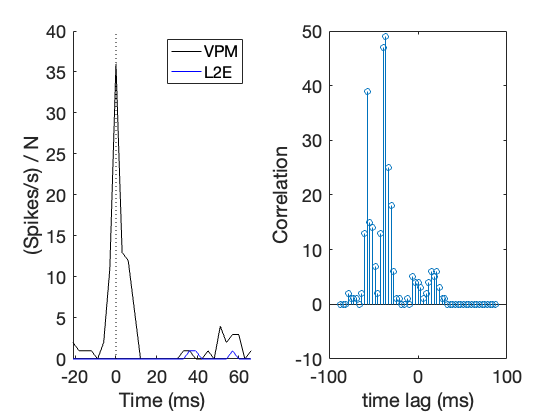


nexttile; stem(lags*binSize_events, cross_corr)
xlabel('time lag (ms)')
ylabel('Correlation')
set(gca,'fontsize',18)

## Bulk analysis

clear all
load '/Users/teatompos/Library/CloudStorage/GoogleDrive-t.tompos@neurophysiology.nl/.shortcut-targets-by-id/1f3yqxuDDFP_-nrGlSKbqcVC3RJJZZWTiWyK5Kl5x65maOi21i1OEIloSOR_UsCfsdiH2FbZf/Lab notebook Tea Tompoš/Thesis/Chapter 2 (The model)/Simulations/ExclusionCriteria/XCorrAnalysis.mat'

% plot results
pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];
binSizes = [3 5 8 10 12];
binLegend = arrayfun(@(num) ['Bin = ' num2str(binSizes(num)), 'ms'], 1:length(binSizes), 'UniformOutput', false);

f1 = figure(1); clf; tiledlayout(6,5)
f2 = figure(2); clf; tiledlayout(6,1)
colorMap = jet(seedNum);

for pIdx = 1:length(pops)
    for bIdx = binSizes
        fractCorr = [];
        
        figure(f1);
        nexttile; title([pops(pIdx,:) '; bin = ' num2str(bIdx) 'ms']);
        hold on;
        for sIdx = 1:seedNum
            color = colorMap(sIdx, :);
            
            if pIdx == 1
                % I forgot to clean the array before populating it with
                % data from the next population, so now I take only the
                % last x number of datapoints, where x is the number of
                % thalamic events which I count here for L4E (this was the
                % first population)
                numEvents = length(XCorrAnalysis.(['seed' num2str(sIdx)]).(pops(pIdx,:)).(['bin_' num2str(bIdx)]));
            end
            
            data = XCorrAnalysis.(['seed' num2str(sIdx)]).(pops(pIdx,:)).(['bin_' num2str(bIdx)])(end-(numEvents-1):end); 
            XCorrAnalysis.(['seed' num2str(sIdx)]).(pops(pIdx,:)).(['bin_' num2str(bIdx)]) = data;
            
            dataPositive = data(~isnan(data));
            
            dataNegative = data(isnan(data));
            dataNegative(isnan(dataNegative)) = 0;
            
            fractCorr(end+1) = length(dataPositive) / (length(dataNegative) + length(dataPositive));
            
            scatter(zeros(1,length(dataPositive))+sIdx, dataPositive,'markerfacecolor', color, 'markeredgecolor', 'none', 'markerfacealpha', 0.2)
            scatter(zeros(1,length(dataNegative))+sIdx, dataNegative,'markerfacecolor', 'k', 'markeredgecolor', 'none', 'markerfacealpha', 0.2)
        end
        xlabel('Seed number')
        xlim([1 seedNum])
        ylabel({'XCORR(CTX w VPM)'; '[peak xcorr value]'})
        
        figure(f2); nexttile(pIdx); hold on;
        plot(1:100, fractCorr, 'linewidth',2)
    end
    legend(binLegend, 'location', 'eastoutside')
    title(pops(pIdx,:))
    xlabel('Seed number')
    xlim([1 seedNum])
    ylabel({'# of corr. events /'; 'total # of events'})
    ylim([0.3 1])
    set(gca,'fontsize', 14)
end